Use ColoredNoise from MATLAB's DSP toolbox to generate three different kinds of noise:

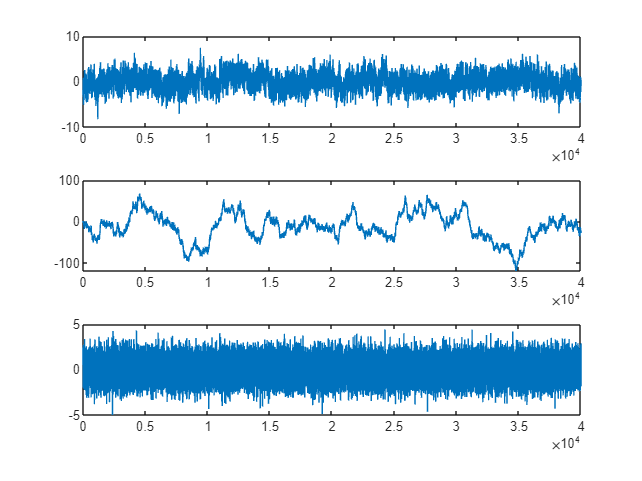

fsNoise = 8000;
channels = 1;

noisegenerator = dsp.ColoredNoise('pink', fsNoise*5, channels, OutputDataType='single');
pinkNoise = noisegenerator();

noisegenerator = dsp.ColoredNoise('brown', fsNoise*5, channels, OutputDataType='single');
brownNoise = noisegenerator();

noisegenerator = dsp.ColoredNoise('blue', fsNoise*5, channels, OutputDataType='single');
blueNoise = noisegenerator();

figure,
subplot(3,1,1), title("pink noise"), plot(pinkNoise);
subplot(3,1,2), title("brown noise"), plot(brownNoise);
subplot(3,1,3), title("blue noise"), plot(blueNoise);

Load a speech sample, downsample (for comparison with model outputs later...?), and create three noised signals:

%sound(pinkNoise,fsNoise)

[speechExample, fsSpeech] = audioread("sample2.wav");
speechDownsampled = mydownsample(speechExample, fsSpeech, fsNoise);

noisyAudioPink = add_noise(speechDownsampled, pinkNoise);
noisyAudioBrown = add_noise(speechDownsampled, brownNoise);
noisyAudioBlue = add_noise(speechDownsampled, blueNoise);

Plot the signals:

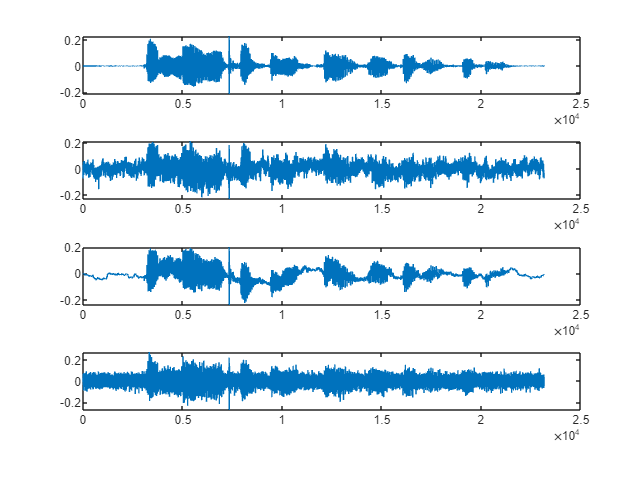

figure,
subplot(4,1,1), title("target"), plot(speechDownsampled)
subplot(4,1,2), title("pink poise added"), plot(noisyAudioPink)
subplot(4,1,3), title("brown noise added"), plot(noisyAudioBrown)
subplot(4,1,4), title("blue noise added"), plot(noisyAudioBlue)

Do objective measure with SI-SDR:

Measure speech against itself:

noNoise = sisdr(speechDownsampled,speechDownsampled)

noNoise = 170.4270

Measure with speech against itself with pink noise added:

pinkNoiseMetric = sisdr(noisyAudioPink, speechDownsampled)

pinkNoiseMetric = single
0.0412

Measure with brown noise added:

brownNoiseMetric = sisdr(noisyAudioBrown, speechDownsampled)

brownNoiseMetric = single
0.6040

Measure with blue noise added:

blueNoiseMetric = sisdr(noisyAudioBlue, speechDownsampled)

blueNoiseMetric = single
-0.0059

Measure speech against pure pink noise:

dur = length(speechDownsampled);

noiseMetric = sisdr(pinkNoise(1:dur), speechDownsampled)

noiseMetric = single
-32.5313

function metric = sisdr(y,target)
%sisdr Scale-Invariant Signal-to-Distortion Ratio (SDR)
% metric = sisdr(estimate,target) calculates the scale-invariant SDR
% described in [1].

y = y - mean(y,1);
target = target - mean(target,1);

alpha = sum(y.*target,1)./(sum(target.^2,1) + eps);

etarget = alpha.*target;
eres = y - etarget;

top = sum(etarget.^2);
bottom = sum(eres.^2);
metric = 10*log(top./(bottom+eps))/log(10);

end